t = linspace(0, 2e-3, 1024);
fs = 1024/2e-3;

sine_1k = sin(2*pi*1e3*t);
sine_3k25 = sin(2*pi*3.25e3*t);
sine_5k5 = sin(2*pi*5.5e3*t);
sine_7k75 = sin(2*pi*7.75e3*t);
sine_10k = sin(2*pi*10e3*t);
sine_12k25 = sin(2*pi*12.25e3*t);
sine_14k5 = sin(2*pi*14.5e3*t);
sine_16k75 = sin(2*pi*16.75e3*t);

sine_total = sine_1k+sine_3k25+sine_5k5+sine_7k75+sine_10k+sine_12k25+sine_14k5+sine_16k75;

% signal_fft = fftshift(fft(sine_total))/length(sine_total);
signal_fft = fftshift(fft(sine_total));
% signal_fft = fft(sine_total);
df = fs/length(sine_total);
half_res = df/2;
freq = -fs/2: df : fs/2 - df;

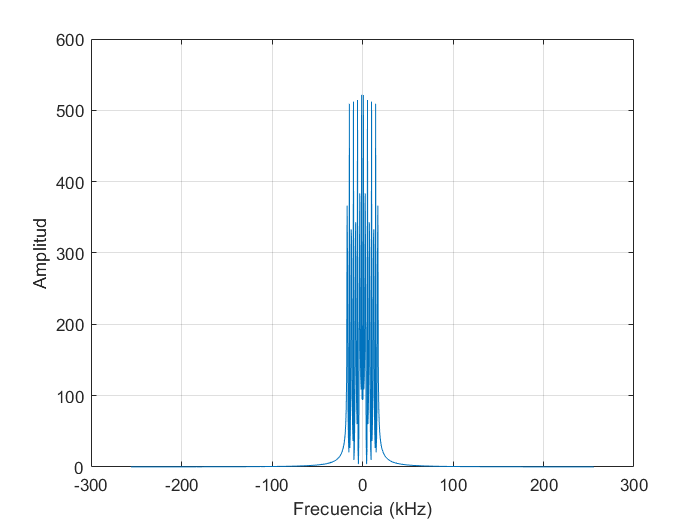

plot(freq/1e3, abs(signal_fft))
grid on
% xlim([-30 30])
xlabel("Frecuencia (kHz)")
ylabel("Amplitud")

mean_values = zeros([1 8]);
abs_fft = abs(signal_fft);
for i = 1:8
    mean_values(i) = mean(abs_fft((32*(i-1)+1):(32*(i)+1)));
end
mean_values

mean_values =     0.1916    0.1966    0.2070    0.2236    0.2479    0.2823    0.3307    0.3995
